# Exercise on exploration and analysis of brain features of the ABIDE sample

Objective: to explore and make statistical analyses of the set of features in /DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males.csv

This dataset contains 419 brain morphological features (volumes, thinckness, area, etc. from the Freesurfer aseg e aparc ouput files) of brain parcels and global measures, derived for 915 male subjects of the Autism Brain Imaging Data Exchange (ABIDE) dataset (see more information at http://fcon_1000.projects.nitrc.org/indi/abide/).

As reported in the README.txt, in addition to brain morphometric features, the following information are specified for each subject in the fists columns:

- subject ID

- age at scan

- sex

- Full intellectual quotient (FIQ)

- diagnostic group (DX_GROUP), which is 1 for ASD, -1 for TD

## To do:

1) Read the features in file /DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males.csv (or in the file /DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males_someGlobals.csv which contains a reduced amount of features) and store them in a table

2) Explore the data table:

        2.1. Have a look at feature names and at subjects' ID

        2.2. Make a box plot of subjects' age by using diagnostic category as grouping variable, put the feature name as title and display the category labels

        2.3. Make a box plot of subjects' age by using provenience site as grouping variable

        2.4. Make a bar plot of subjects' age highlighting provenience site and diagnostic category

        2.5. Display the histograms of 16 randomly-chosen features from the dataset, visualizing on the same plot both diagnostic categories

3) Find outliers in the feature distributions

- Define an outlier as an element of the features distribution with a value that deviates more than three standard deviations from the mean.

- Delete the subjects with outlier features from the dataset (use `rmoutliers`)

4) Are cases and controls matched for age and for FIQ?

- Make a statistical comparison of subjects' age between cases and controls    

- Make a statistical comparison of subjects' FIQ between cases and controls 

5) Is there any statistically significant difference between features of cases and controls?

- Make a statistical comparison between the brain features of ASD and CTR

- Build a L-R asimmetry measure of cortical thickness and test if it is different between ASD and CTR

6) Is there any significant correlation between age and average thickness of gray matter?

7) Is the age trend of cortical thickness different between cases and controls?

Before we start, it is better to close all figures and to clean the workspace.

clear
close all

## 1) Read the features 

Read the features in file /DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males.csv (or in the file /DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males_someGlobals.csv which contains a reduced amount of features) and store them in a table

filename = '/Users/linda/Desktop/materiali università/magistrale/Computing methods for experimental physics/Imaging/some imaging data/FS_features_ABIDE_males.csv';
data = readtable(filename);

## 2) Explore the data table:

###     2.1. Have a look at feature names and at subjects' ID

data.FILE_ID
data.Properties
data.Properties.VariableNames

###     2.2. Make a box plot of subjects' age by using diagnostic category as grouping variable, put the feature names as title, and display the category labels

Use the Matlab `boxplot` function with the appropriate grouping variable 

h = boxplot(data.AGE_AT_SCAN, data.DX_GROUP, 'Colors','rb','MedianStyle','line','Symbol','o','Labels',{'TD (-1)','ASD (1)'})
title("Subjects' age");
grid on

###     2.3. Make a box plot of subjects' age by using provenance site as grouping variable

Use the Matlab `boxplot` function with the appropriate grouping variable. A categorical variable reporting the site information can be generated for each subject from the FILE_ID using the split function. Add the site field to the data table.

Let's create a categorical variable with site information:

% fileID_parts = split(data.FILE_ID,'_00'); % boxplot is too slow with this
site = categorical(extractBefore(data.FILE_ID,'_'));
% site = categorical(fileID_parts)

We can add site as a field in the table

data.Site = site;
data.Properties.VariableNames % check the added column

Make the box plot of subjects' age grouped by site

B = boxplot(data.AGE_AT_SCAN, data.Site, 'Colors','brgcmyk','MedianStyle','line','Symbol','o')
title("Subjects' age, grouped by provenance site");
grid on

The grouping variable names (sites) are not visible, we can rotate them 

% angle = 30; xtickangle(angle)

###     2.4. Make a bar plot reporting the number of subjects' for each site, highlighting the two components of the two diagnostic category as stacked bars.

Find the unique elements in the site vector with `unique` and then use `histcounts` to count the number of times each unique element appears. Then, use `bar` to make a bar plot.

[`C`](https://localhost:31515/static/help/matlab/ref/unique.html?searchHighlight=unique&searchResultIndex=1#bs_6vpd-1-C) `=` `unique``(`[`A`](https://localhost:31515/static/help/matlab/ref/unique.html?searchHighlight=unique&searchResultIndex=1#bs_6vpd-1-A)`)` returns the same data as in `A`, but with no repetitions. `C` is in sorted order.

[Site_names, ia, ic] = unique(data.Site);

To count the number of times each element in `Site_names` appears in data.site, you can use `histcounts`

site_counts = histcounts(ic, 'BinMethod','integers');

Make visible the two different diagnostic categories (use `bar`, with the 'stacked' option): ic contains the site label for each case, we have to split ic according to the diagnostic category and then count the number of entries of two cohorts with `histcounts`.

counts_ASD = histcounts(ic(data.DX_GROUP == 1), 1:length(site_counts)+1);
counts_TD = histcounts(ic(data.DX_GROUP == -1), 1:length(site_counts)+1);
counts = [counts_ASD; counts_TD]';
figure; bar(counts, 'stacked');
legend({'ASD','TD'});
ylabel('Number of subjects');
set(gca, 'XTick', 1:length(Site_names), 'XTickLabel', Site_names);
title('Subjects per site and diagnosis');
grid on

###     2.5. Display the histograms of 4 randomly-chosen features from the dataset, visualizing on the same plot both diagnostic categories

Use `datasample` to randomly sample from data, with or without replacement

[`y`](https://it.mathworks.com/help/stats/datasample.html#bs10l6i-y) `= datasample(`[`data`](https://it.mathworks.com/help/stats/datasample.html#bs10l6i-data)`,`[`k`](https://it.mathworks.com/help/stats/datasample.html#bs10l6i-k)`)` returns *k* observations sampled uniformly at random, with replacement, from the data in `data`.

[`y`](https://it.mathworks.com/help/stats/datasample.html#bs10l6i-y)` = datasample(`[`data`](https://it.mathworks.com/help/stats/datasample.html#bs10l6i-data)`,`[`k`](https://it.mathworks.com/help/stats/datasample.html#bs10l6i-k)`,'Replace'``,false) -> `without replacement

N = 4;
L = ceil(sqrt(N));
figure;
% The features are from data.Properties.VariableNames(6) to (12)
feat_index = datasample(6:12, N, 'Replace', false);
for ip = 1:N
    subplot(L,L,ip)
    H = histogram(data{data.DX_GROUP==1, feat_index(ip)});
    xlabel(data.Properties.VariableNames(feat_index(ip)));
    ylabel('Counts ');
    hold on
    histogram(data{data.DX_GROUP==-1, feat_index(ip)}, H.BinEdges);
end
sgtitle('Histograms of features of ASD and TD subjects ')
legend('ASD', 'TD');

Notice that to maintain the same bin widths for the ASD and CTR histograms, we can adopt in the second histogram of each plot the bin edges automatically selected in the first histogram of the same plot.

## 3) Find outliers in the feature distributions

- Define an outlier as an element of the features distribution with a value that deviates more than three standard deviations from the mean.

- Delete from the dataset the subjects with outlier features (use `rmoutliers`)

[`B`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_0b8a542a-a13a-466b-a01e-8554046d239d) `= rmoutliers(`[`A`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_006e6301-85b2-4515-874a-3d398a655313)`)` detects and removes outliers from the data in a vector, matrix, table, or timetable.

- If `A` is a row or column vector, `rmoutliers` detects outliers and removes them.

- If `A` is a matrix, table, or timetable, `rmoutliers` detects outliers in each column or variable of `A` separately and removes the entire row.

[`B`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_0b8a542a-a13a-466b-a01e-8554046d239d) `= rmoutliers(`[`A`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_006e6301-85b2-4515-874a-3d398a655313)`,`[`method`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_f334bff5-af8a-45f3-a025-2d4bb1909464)`)` specifies a method for determining outliers. For example, `rmoutliers(A,'mean') `defines an outlier as an element of `A` more than three standard deviations from the mean.

Feature_var = data.Properties.VariableNames(6:12) % we have 7 features 
outvalues = isoutlier(data(:,Feature_var), 'mean');

Notice also that the logical array (`outvalues`) containing the information about outliers in the dataset can be visualized as a mask. Display `outvalues` as an image to get a visual feedback about the presence of outliers in the dataset.

figure; imagesc(outvalues)
xticks(1:numel(Feature_var));
xticklabels(Feature_var);
title('Detected outliers in some features')
% angle = 30; xtickangle(angle);

`Remove outliers `with [`B`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_0b8a542a-a13a-466b-a01e-8554046d239d)` = rmoutliers(`[`A`](https://localhost:31515/static/help/matlab/ref/rmoutliers.html#mw_006e6301-85b2-4515-874a-3d398a655313)`)` 

`B = rmoutliers(A,method)`

For methods `'mean'` the number of standard deviations from the mean is 3 by default.

`[`[`B`](https://it.mathworks.com/help/matlab/ref/rmoutliers.html?searchHighlight=rmoutliers&s_tid=doc_srchtitle#mw_0b8a542a-a13a-466b-a01e-8554046d239d)`,`[`TF`](https://it.mathworks.com/help/matlab/ref/rmoutliers.html?searchHighlight=rmoutliers&s_tid=doc_srchtitle#mw_a1e1dca5-0a1a-4938-aeef-477117b0900b)`] =` `rmoutliers``(``___``)` also returns a logical vector corresponding to the rows or columns of `A` that were removed.

Complete_Feature_var = data.Properties.VariableNames(6:423);
[data_1, TF] = rmoutliers(data(:,Complete_Feature_var),'mean');
data_NoOut = data;
data_NoOut(TF,:) = []; % we need all columns so we delete the TF rows from the initial data table

Visual assessment of the histogram after removing outliers

N = 4;
L = ceil(sqrt(N));
figure;
% The features are from data.Properties.VariableNames(6) to (12)
feat_index = datasample(6:12, N, 'Replace', false);
for ip = 1:N
    subplot(L,L,ip)
    K = histogram(data_NoOut{data_NoOut.DX_GROUP==1, data_NoOut.Properties.VariableNames(feat_index(ip))});
    xlabel(data_NoOut.Properties.VariableNames(feat_index(ip)));
    ylabel('Counts ');
    hold on
    histogram(data_NoOut{data_NoOut.DX_GROUP==-1, data_NoOut.Properties.VariableNames(feat_index(ip))}, K.BinEdges);
end
sgtitle('Histograms of features of ASD and TD subjects, without outliers ')
legend('ASD', 'TD');

Who are the outliers?

data.FILE_ID(TF)

For instance, many of them are from SBL site. 

To count them:

sum(contains(data.FILE_ID,'UM'))
sum(contains(data.FILE_ID(TF),'UM'))

Out of a total amount of 30 subjects from 'SBL', 29 are outliers.

The maximum relative amount of outlier seems to be from the UM site, though.

## 4) Are cases and controls matched for age and for FIQ?

- Make a statistical test to compare subjects' age between cases and controls    

- Make a statistical test to compare test on subjects' FIQ between cases and controls 

Use `ranksum `(Wilcoxon rank-sum test, non-parametric equivalent of t-test, i.e. data is not assumed to be normally distributed).

It takes only numerical vectors as input, so we have to convert the columns of interest with `table2array` and analyze one feature at a time 

Age_ASD = table2array(data_NoOut(data_NoOut.DX_GROUP==1,"AGE_AT_SCAN"));
Age_CTR = table2array(data_NoOut(data_NoOut.DX_GROUP==-1,"AGE_AT_SCAN"));
[p1,h1] = ranksum(Age_ASD(:,1), Age_CTR(:,1))

Result: the two groups are matched on age (check out the p-value, notice that h1 = logical 0). Let's test the FIQ.

fiq_ASD = table2array(data_NoOut(data_NoOut.DX_GROUP==1,"FIQ"));
fiq_CTR = table2array(data_NoOut(data_NoOut.DX_GROUP==-1,"FIQ"));
[p2,h2] = ranksum(fiq_ASD(:,1), fiq_CTR(:,1))

Result: the two groups are independent basing on the FIQ feature (notice that h2 = logical 1, i.e. null hypotesis can be rejected - this latter being the assumption of the two groups being matched, i.e. equally distributed).

## 5) Is there any statistically significant difference between features of cases and controls?

- Make a statistical test to compare the brain features of ASD and CTR. (We use the ttest2 which supports a multidimensional array). 

T_ASD = data_NoOut{data_NoOut.DX_GROUP == 1, Feature_var};
T_CTR = data_NoOut{data_NoOut.DX_GROUP == -1, Feature_var};
[h_without, p_without] = ttest2(T_ASD, T_CTR)
complete_ASD = data{data.DX_GROUP == 1, Feature_var};
complete_CTR = data{data.DX_GROUP == -1, Feature_var};
[h_with, p_with] = ttest2(complete_ASD, complete_CTR)

Significant statistical differences have been detected for the 7 global features we are considering.

### Build a L-R asimmetry index (LR) for cortical thickness and test if it is different between ASD and CTR

LR = (data.lh_MeanThickness - data.rh_MeanThickness);
X = data.AGE_AT_SCAN;
X_ASD = X(data.DX_GROUP==1);
X_CTR = X(data.DX_GROUP==-1);
LR_ASD = LR(data.DX_GROUP==1);
LR_CTR = LR(data.DX_GROUP==-1);

- Make a plot to show the LR asymmetry as a function of age.

figure; plot(X_ASD', LR_ASD', 'xb', X_CTR', LR_CTR', 'xr')
xlabel('Age at scan');
ylabel('Left-right asymmetry of cortical thickness');
legend('ASD', 'TD')

- Check for a statistical significance of L-R asimmetry in cortical thickness

[h_LR, p_LR] = ttest2(LR_ASD, LR_CTR)
%[p_LR, h_LR] = ranksum(LR_ASD, LR_CTR)

The difference is statistically significant!

What about L-R asymmetry index for cortical thickness and its statistical significance if outliers are removed?

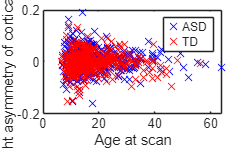

LRo = (data_NoOut.lh_MeanThickness - data_NoOut.rh_MeanThickness);
Xo = data_NoOut.AGE_AT_SCAN;
X_ASDo = Xo(data_NoOut.DX_GROUP==1);
X_CTRo = Xo(data_NoOut.DX_GROUP==-1);
LR_ASDo = LRo(data_NoOut.DX_GROUP==1);
LR_CTRo = LRo(data_NoOut.DX_GROUP==-1);
figure; plot(X_ASDo', LR_ASDo', 'xb', X_CTRo', LR_CTRo', 'xr')
xlabel('Age at scan');
ylabel('Left-right asymmetry of cortical thickness');
legend('ASD', 'TD')
[h_LRo, p_LRo] = ttest2(LR_ASDo, LR_CTRo)

%[p_LR, h_LR] = ranksum(LR_ASDo, LR_CTRo)

Now p-value is much larger than before.

- Visualize the box plots for the LR index, categorized by diagnosis.

figure;

h_LR = 1

p_LR = 8.0037e-04

boxplot(LR, data.DX_GROUP, 'Colors','rb','MedianStyle','line','Symbol','o','Labels',{'TD (-1)','ASD (1)'})
title("Box plot of subjects' LR asymmetry index")
grid on

We can compute the effect size in terms of Cohen's *d* 


$$d = \frac{\mu_1-\mu_2}{\sigma_{pool}}$$


where ${\sigma_{pool}}$ is the pooled standard deviation 

d = (mean(LR_ASD)-mean(LR_CTR))/std(LR)

*d *= 0.23 is considered to be an effect between small and medium. 

## 6) Is there any significant correlation between age and average thickness of grey matter?

- Average the L and R mean thickness and display a scatter plot of mean thickness vs. age.  

avg_MT = (data.lh_MeanThickness + data.rh_MeanThickness)/2;
figure; scatter(data.AGE_AT_SCAN, avg_MT, 'filled')
xlabel('Age at scan');
ylabel('Average left and right mean grey matter thickness ');

- Evaluate the Pearson correlation between thickness and age with `corr`, and display the p value 

[rho_thick_age, p_thick_age_corr] = corr(data_NoOut.AGE_AT_SCAN, (data_NoOut.rh_MeanThickness+data_NoOut.lh_MeanThickness)/2)

- Display the scatter plot and check the correlation between mean thickness and TotalGrayVol.  

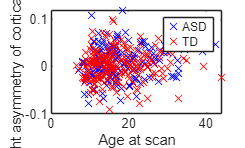

figure; scatter(data.TotalGrayVol, avg_MT, 'filled')
xlabel('Total volume of grey matter');
ylabel('Average left and right mean grey matter thickness ');
[rho_thick_V, p_thick_V_corr] = corr(data.TotalGrayVol, avg_MT)

There is a significant correlation between mean thickness and TotalGrayVol.

In general, when comparing the features of two cathegories of subjects, we have to account for subjects' age, global volume and other confounding factors, expecially when these variables are not matched between the two groups. 

## 7) Is the age trend of cortical thickness different between cases and controls?

Make a scatter plot of mean thickness (L-R average) and age, using different colours for ASD and CTR subjects.

avg_MT = (data.lh_MeanThickness + data.rh_MeanThickness)/2;

h_LRo = 0

p_LRo = 0.0985

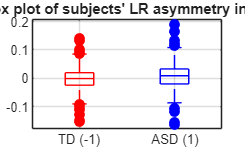

X = data.AGE_AT_SCAN;
X_ASD = X(data.DX_GROUP==1);
X_CTR = X(data.DX_GROUP==-1);
MT_ASD = avg_MT(data.DX_GROUP==1);
MT_CTR = avg_MT(data.DX_GROUP==-1);
figure; plot(X_ASD', LR_ASD', 'xb', X_CTR', LR_CTR', 'xr')
xlabel('Age at scan');
ylabel('Average left and right mean grey matter thickness ');

legend('ASD', 'TD')

Compute the correlation coefficients for the two dataset separatly

[rho_thick_age_ASD, p_thick_age_corr_ASD] = corr(X_ASD, MT_ASD)

d = 0.2212

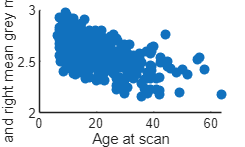

rho_thick_age = -0.6463

p_thick_age_corr = 5.8344e-46

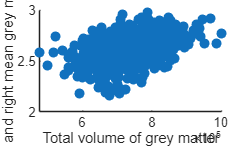

rho_thick_V = 0.4713

p_thick_V_corr = 8.8427e-52

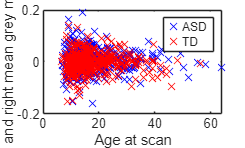

rho_thick_age_ASD = -0.5863

p_thick_age_corr_ASD = 5.5401e-43

rho_thick_age_CTR = -0.5968

p_thick_age_corr_CTR = 4.2038e-46

[rho_thick_age_CTR, p_thick_age_corr_CTR] = corr(X_CTR, MT_CTR)

We found out very similar values for the two groups.